Matlab IC04 Script: 

% -- ORIGINAL DATA: --------------------------
x1 = [46, 49, 51, 52, 54, 56, 57, 58, 59, 60];
y1 = [40, 50, 55, 63, 72, 70, 77, 73, 90, 93];
deg1 = (length(x1)-1);
rr1 = zeros(1,deg1);
%-------
x2 = [61, 62, 63,  64,  66,  67,  68,  71,  72];
y2 = [96, 88, 99, 110, 113, 120, 127, 137, 132];
deg2 = (length(x2)-1);
rr2 = zeros(1, deg2);

Part 1: Use Polyfit to fit the data with several low-order polynomials

Part 2: Plot the Data Set and the Polynomials (x increments by 1) on the Same Graph

Part 3: Compute & Plot the R^2 value as a function of Polynomial Degree

% -- FITTED POLYNOMIALS: ---------------------
xx1=min(x1):1:max(x1);
%subplot(2,1,1);
figure(1); hold on;
plot(x1, y1, '*', 'DisplayName', 'Original Data Set 1');
for i=1:deg1
    C1 = polyfit(x1, y1, i);
    yy1 = polyval(C1, xx1);
    plot(xx1, yy1, 'DisplayName', sprintf('Data Set 1: Degree %d', i));
    %-- COMPUTE R^2 VALUES: ----------------------
    yy1_err = polyval(C1, x1);
    SST1 = sum((y1-mean(y1)).^2);
    SSE1 = sum((y1-yy1_err).^2);
    rr1(i) = 1- (SST1 / SSE1);
    %fprintf('R-sq. Value for Data Set 1 w/ Degree %d:\n', i);
    %fprintf('R-sq = %f', rr1(i));
end

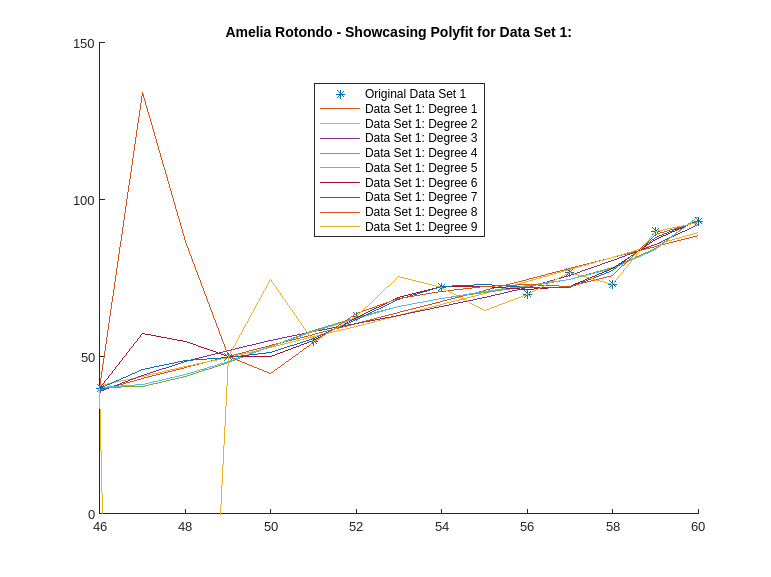

hold off;
title('Amelia Rotondo - Showcasing Polyfit for Data Set 1:')
ylim([0, 150]);
legend('Location','best');

%-------
xx2=min(x2):1:max(x2);
%subplot(2,1,2);
figure(2); hold on;
plot(x2, y2, '*', 'DisplayName', 'Original Data Set 2');
for i=1:deg2
    C2 = polyfit(x2, y2, i);
    yy2 = polyval(C2, xx2);
    plot(xx2, yy2', 'DisplayName', sprintf('Data Set 2: Degree %d', i));
    %-- COMPUTE R^2 VALUES: ----------------------
    yy2_err = polyval(C2, x2);
    SST2 = sum((y2-mean(y2)).^2);
    SSE2 = sum((y2-yy2_err).^2);
    rr2(i) = 1 - (SST2 / SSE2);
    %fprintf('R-sq. Value for Data Set 2 w/ Degree %d:\n', i);
    %fprintf('R-sq = %f', rr2(i));
end

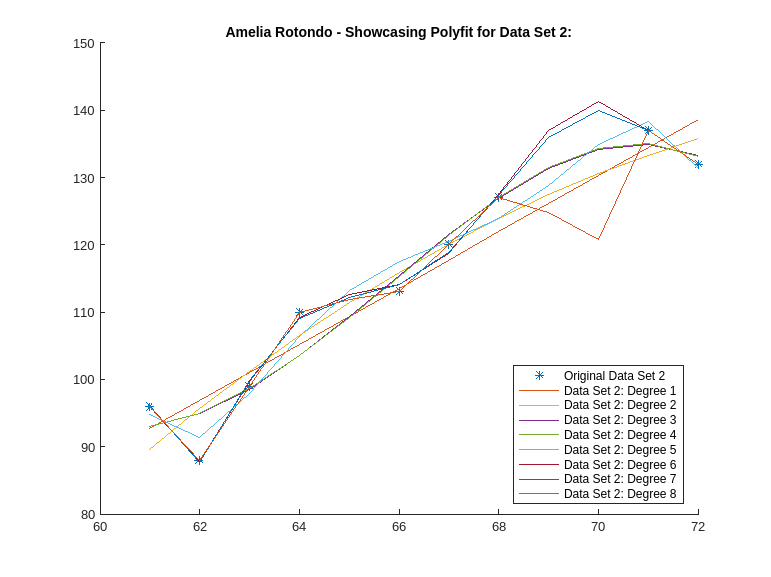

hold off; 
title('Amelia Rotondo - Showcasing Polyfit for Data Set 2:')
legend('Location','best');


%-- DISPLAY THE R^2 VALUES -----------------------
fprintf('R^2 Values for Data Set 1 (from degree 1 to 9):\n %8f %8f %8f %8f %8f %8f %8f %8f %8f', rr1);

R^2 Values for Data Set 1 (from degree 1 to 9):
 -13.974692 -14.508340 -17.574157 -25.071669 -25.148905 -45.276146 -46.823028 -61.464791 -1697567.174015

fprintf('\nR^2 Values for Data Set 2 (from degree 1 to 8):\n %8f %8f %8f %8f %8f %8f %8f %8f', rr2);


R^2 Values for Data Set 2 (from degree 1 to 8):
 -10.596120 -13.273292 -19.376473 -19.392936 -37.889249 -524.058838 -544.702620 -22581003.381748

Part 4: Down-Select Polynomials to One, and Discuss why You Chose It

I chose polyfit (x2, y2, 1), which for my data- is the polynomial of degree 1 that fits the second data set. I chose this because it has the lowest R^2 value out of all the other values provided, at -10.596120.

The polynomial is as follows: 4.1833x - 162.5444

Since the data isn't a clear line, and appears more cubic than anything else, I found it interesting that this line still provided the lowest R^2 value. I would not have expected this outcome, yet after looking at the graphs developed that include this line, I understand how it was achieved.